# 선형 시스템의 응용 사례

 이 라이브 스크립트는 표시된 코드와 함께 사용하도록 설계되었습니다. `VIEW` 탭을 선택하고 `Output Inline` 으로 전환합니다. 

## 선형 회귀

선형 회귀는 전통적인 분야(물리학 및 화학)와 새로운 분야(기계 학습 및 데이터 과학)의 필수 요소입니다. 이 섹션에서는 선형 회귀 문제에 대한 최소 제곱 솔루션을 도출합니다. 

** 데이터 **

 아래 표시된 임의 데이터에 대한 선형 관계를 추정한다고 가정합니다. 

n = 31;
 

x = sort(normrnd(5,1.75,n,1));
y = 1*normrnd(2,0.6,n,1) + x*(0.2+rand(1,1)/2);

scatter(x,y,"filled")
xlabel("x")
ylabel("y")
axis([0 10 0 10])

  ** 실습. ** 이 섹션을 실행하여 데이터를 생성합니다. 

** 잔차 **

 $x$와 $y$ 사이의 관계는 선형 함수로 근사화될 수 있습니다. 

    
$$f(x) = w_0 + w_1 x$$


 일반적으로 가장 적합한 선은 제곱합 오류를 최소화하는 선으로 선택됩니다. 이 오차를 잔차라고 합니다. 

    
$$R(w_0,w_1) = \sum_i [ y_i - (w_0 + w_1 x_i) ]^2$$


 시각적으로 잔차는 선과의 수직 차이의 제곱을 합하여 계산됩니다. 

w0 = 1.4;
w1 = 0.8;
 

f = @(x) w0 + w1*x;
R = sum( (y - f(x)).^2 );

scatter(x,y,"filled")
hold on
plot([0 12],f([0 12]),"k-")
plot([x x]',[f(x) y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
axis([0 10 0 10])

  ** 실습. ** 선형 함수의 매개변수를 조정하여 제곱 오차의 합을 줄입니다. 

**행렬 형식로 선형 근사 작성 **

잔차 $R$을 최소화하는 매개변수 $w_1$ 및 $w_2$를 찾기 위해 최소 제곱 솔루션을 풀 수 있습니다. 

이 시스템을 설정하려면 벡터 측면에서 데이터( $x_i$ 및 $y_i$ )를 작성합니다: 

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$ 및 $\mathbf{y} = \left( \matrix{ y_1 \cr y_2 \cr \vdots \cr y_n } \right)$

 그런 다음 선형 근사 벡터 $\tilde{\mathbf{y}} = w_0 + w_1 \mathbf{x}$를 선형 조합으로 작성합니다: 

     $\tilde{\mathbf{y}} = w_0 \left( \matrix{ 1 \cr 1 \cr \vdots \cr 1} \right)
+ w_1 \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$ 이는 행렬 형식과 동일합니다. : $\tilde{\mathbf{y}} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) \left( \matrix{ w_0 \cr w_1 } \right)
$. 

 이는 

    $\mathbf{X} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) $ 및 벡터 $\mathbf{w} = \left( \matrix{ w_0 \cr w_1 } \right)$인 경우 

    
$$\tilde\mathbf{y} = \mathbf{Xw}$$


로 작성할 수 있습니다. 

** 연습 **. 이 연습에서는 MATLAB을 사용하여 예제 위에 설명된에 대한 대략적인 해 $\tilde\mathbf{y} $를 행렬 형식으로 작성합니다. 

 1. 변수 `u`에 포함된 열을 벡터 `x `(데이터의 $x$ -위치를 저장함)와 연결하여 행렬 $\mathbf{X}$를 정의합니다. `[a b]` 구문을 사용하여 두 개의 열 벡터 `a` 및 `b`를 [합치는 것(concatenate)](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html#OverviewCreatingAndConcatenatingExample-3)이 가능합니다. 

u = ones(n,1); % 1로 구성된 벡터
% X를 정의합니다:


 2. 변수 `w0` 및 `w1`를 사용하여 벡터 $\mathbf{w}$를 정의합니다. 

 3. 선형 근사 y 값을 계산합니다: $\tilde\mathbf{y} = \mathbf{Xw}$. MATLAB 변수 `y_approx` 에 $\tilde{\mathbf{y}$ 을 할당합니다. 

** 데이터의 선형 근사치를 시각화합니다. **

  ** 실습. ** 이 섹션을 실행하면 `y_approx` 에 저장된 추정치를 시각화할 수 있습니다. 

 
try  
    fls = @(x) w(1) + w(2)*x;
    R = sum( (y - fls(x)).^2 );

    scatter(x,y,"filled")
    hold on
    scatter(x,y_approx,'s',"filled")
    plot([0 12],fls([0 12]),"k:")
    plot([x x]',[fls(x) y]',"r:")
    hold off
    title("R(w_0,w_1) = " + num2str(R))
    xlabel("x")
    ylabel("y")
    leg = legend('Data',"$\tilde{\mathbf{y}}$");
    set(leg,"interpreter","latex")
    axis([0 10 0 10])
    
    chi=get(gca, 'Children');
    set(gca, 'Children',flipud(chi));
catch ME
    warning("Plot failed because: "+ME.message)
end

** 최소 제곱 문제의 해법 **

** 일반 해법 **

 선형 회귀 문제에서 제곱 오류의 합을 최소화하려고 합니다. 미적분학 접근법이 여기에 나와 있습니다. 잔차는 행렬 요소의 관점에서 

    
$$\begin{array}{rl}
R(w_0,w_1) &= \sum_i [ y_i - (w_0 + w_1 x_i) ]^2
\\
 &= \sum_i (y_i - \tilde{y}_i )^2
\\
 &= \sum_i \left(y_i -  \sum_j X_{ij} w_{j} \right)^2
\end{array}
$$


으로 작성할 수 있습니다. 미적분학 접근법을 사용하여 $w_i$에 대해 이 방정식을 최소화하려면 정류점(stationary point)을 찾아야 합니다. 이를 위해 도함수 $\frac{\partial}{\partial w_k}$를 가져와 0으로 설정합니다. 

    
$$\begin{array}{rl}
\frac{\partial}{\partial w_k} R(w_0,w_1)  &= \sum_i 2\left( y_i - \sum_j X_{ij} w_{j} \right) \frac{\partial}{\partial w_k} \left(y_i - \sum_j  X_{ij} w_{j} \right)
\\
0 &= 2\sum_i  \left( y_i - \sum_j X_{ij} w_{j} \right) ( - X_{ik} )
\\
0 &= \sum_i  - y_i X_{ik} + \sum_{ij} X_{ij} w_{j} X_{ik} 
\end{array}
$$


 행렬 표기법으로 최종 방정식을 다음과 같이 작성할 수 있습니다. 

    
$$\begin{array}{rl}
0 &= -\mathbf{y}^\top \mathbf{X} + \mathbf{X}^\top \mathbf{X}\mathbf{w} 
\\
\mathbf{X}^\top \mathbf{X}\mathbf{w} & = \mathbf{X}^\top \mathbf{y}
\end{array}$$


 이 시스템의 해 $\mathbf{w}$는 잔차 함수 $R$의 임계점(critical point)입니다. 이것이 잔차를 최소화한다는 것을 입증하려면 추가 인수(여기에는 표시되지 않음)가 필요합니다(잔차의 원래 2차 형태로 인해 직관적임). 

 계수 $\mathbf{w}$에 대한 이 시스템을 풀려면 행렬 시스템을 풀기 위한 표준 방법을 사용할 수 있습니다. 이 결과를 행렬 형식의 선형 시스템의 표준 형식과 비교하십시오. 

    
$$\mathbf{X}^\top \mathbf{X}\mathbf{w}  = \mathbf{X}^\top \mathbf{y}$$
 
$$\Leftrightarrow$$

$$\mathbf{Aw} = \mathbf{b}$$
 

 이 시스템은 $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ 및 $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$ 과 동일합니다. 

** 연습 **. 방정식 

    
$$\mathbf{X}^\top \mathbf{X}\mathbf{w}  = \mathbf{X}^\top \mathbf{y}$$


을 사용하여 선형 회귀 문제의 최소 제곱 솔루션을 찾을 수 있습니다. 이렇게 하려면 행렬 $\mathbf{A}$ 및 우변의 벡터 $\mathbf{b}$를 정의한 다음 행렬 해를 구하면 됩니다. 

 1. $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ 및 $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$ 수식을 사용하여 행렬 `A` 및 우변의 벡터 `b`를 계산합니다. 

** 힌트 ** : 아포스트로피(')를 사용하여 [행렬 전치](https://www.mathworks.com/help/matlab/ref/ctranspose.html)를 계산합니다. 

 2. 백슬래시 연산자를 사용하여 행렬 솔루션을 계산합니다. 결과를 `w` 에 저장합니다. 

 참고: 해를 계산하기 위해 `A` 및 `b`를 정의할 필요는 없습니다. 표현을 직접 사용할 수 있습니다. 

** 최소제곱 피팅을 시각화합니다. **

  ** 실습. ** 해가 완성되면(즉, $\mathbf{w}$ 에 대한 해를 구함) 이 섹션을 실행하여 최소 제곱 해를 볼 수 있습니다. 

 
try
    fls = @(x) w(1) + w(2)*x;
    R = sum( (y - fls(x)).^2 );
    scatter(x,y,"filled")
    hold on
    plot([0 12],fls([0 12]),"k-")
    plot([x x]',[fls(x) y]',"r")
    hold off
    
    title("R(w_0,w_1) = " + num2str(R))
    xlabel("x")
    ylabel("y")
    axis([0 10 0 10])
catch ME
    warning("Plot failed because: "+ME.message)
end

-  수동 피팅 잔차가 최소 제곱 피팅 잔차에 얼마나 가깝습니까? 

## 선형 회로

키르히호프의 회로 법칙을 사용하여 간단한 선형 회로를 분석할 수 있습니다. 행렬은 자연스러운 프레임워크를 제공합니다. 즉, 행렬을 이용해 회로 네트워크를 모델링하는 많은 선형 방정식을 간결하게 표현할 수 있습니다. 이 섹션에서는 선형 회로를 나타내는 선형 방정식의 행렬 형식을 유도하고 해당 회로의 전류 해를 구합니다. 

** 키르히호프의 전류 법칙 **

 노드에 흐르는 모든 전류의 합은 노드에서 흐르는 전류의 합과 같습니다. 

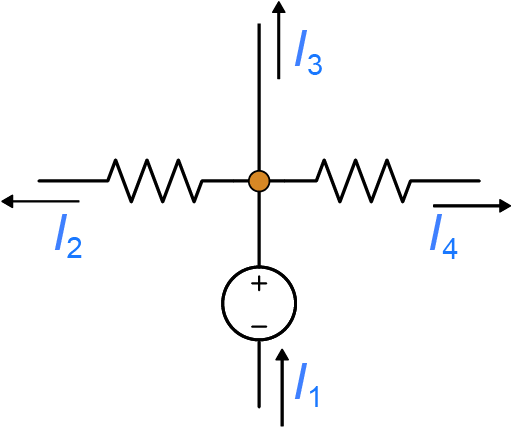

* 이 노드에서 키르히호프의 전류 법칙은 *$I_1 = I_2 + I_3 + I_4 $

** 키르히호프의 전압 법칙 **

 회로의 폐루프 주위의 전압 합은 0입니다. 수학적으로 표현하면 아래와 같습니다. 

    
$$\sum_{k} V_k = 0$$


 여기서 $V_k$는 회로의 $k$ 번째 분기(branch)에 걸친 전위차입니다. 옴의 법칙을 적용하면 각 저항기의 전위 강하가 제공됩니다. $V = IR$. 

 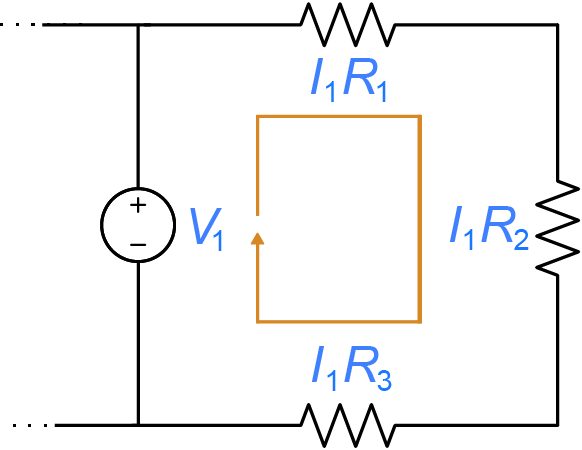

* 이 닫힌 루프에서 저항에 걸리는 전위 강하는 전압 소스에 의해 생성된 전위와 동일해야 합니다. *$V_1 - I_1 R_1 - I_1 R_2 - I_1 R_3 = 0$

** 회로의 매트릭스 표현 **

 이 섹션에서 그림에 있는 선형 회로는 키르히호프의 법칙을 사용하여 매트릭스 형식으로 분석됩니다.. 

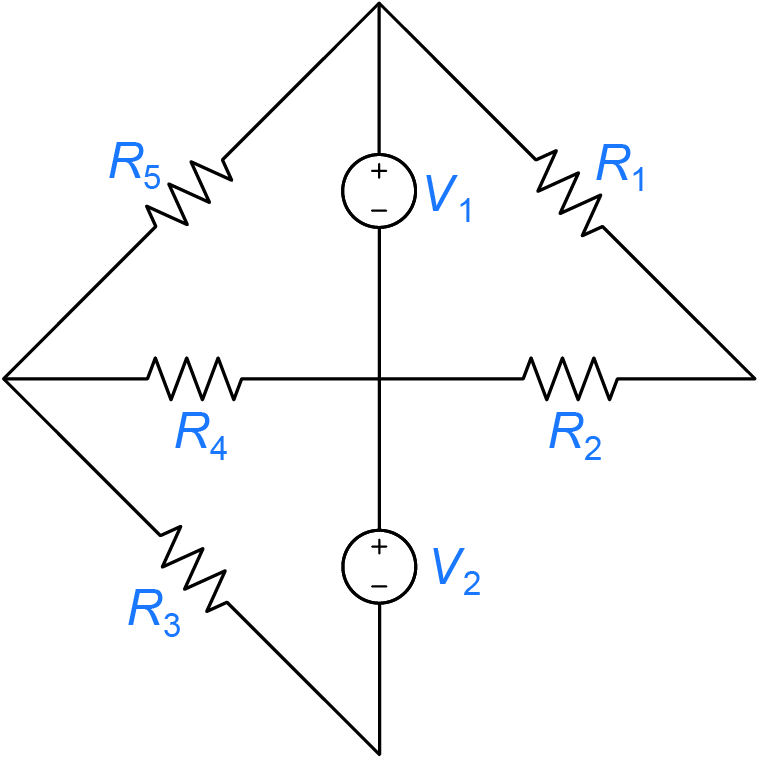

* 분석할 회로 *

** 방정식 유도 **

 방정식을 작성하기 전에 회로를 통과하는 전류 경로를 정의하는 것이 유용합니다. 이는 키르히호프의 법칙을 적용하기 위한 틀을 제공합니다. 반대 방향으로 흐르는 전류는 음수 값으로 표시되므로 전류 경로는 임의적입니다. 키르히호프 법칙의 올바른 형태를 결정하려면 선택한 참조 방향이 필요합니다. 

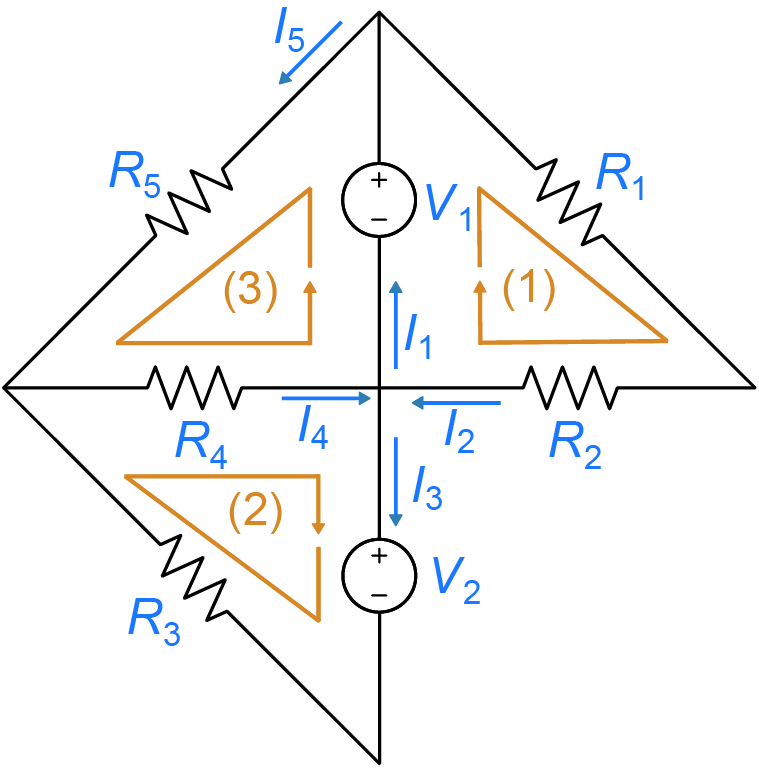

* 이 다이어그램에서는 회로의 세 개의 닫힌 루프가 (1), (2) 및 (3)으로 표시되어 있습니다. 회로의 고유한 전류에도 레이블이 지정되어 있습니다. *

**키르히호프의 전류 법칙 **을 중앙 노드에 적용하면 다음이 생성됩니다. 

    
$$I_2 + I_4 = I_1 + I_3$$


**키르히호프의 전압 법칙 **을 세 개의 루프에 적용하면 3개의 추가 방정식이 추가됩니다. 

    
$$\begin{array}{rl} 
\ V_1 - I_2 R_1 - I_2 R_2  &= 0
\\
- V_2 - I_3 R_3 - I_4 R_4  &= 0
\\
\ V_1 - I_5 R_5 - I_4 R_4  &= 0
\end{array}$$


 이 시점에서 5개의 알려지지 않은 전류가 있지만 4개의 방정식만 있습니다. 연립 방정식의 전체 표현을 완성하려면 키르히호프 전류 법칙을 다시 적용해야 합니다. 가장 위에 위치한 노드에 대해: 

    
$$I_1 = I_2 + I_5$$


 키르히호프의 법칙을 적용할 수 있는 추가 루프와 노드가 있지만 모두 조건이 중복됩니다. 

** 방정식의 행렬 형식 유도 **

 이 방정식을 행렬 형식 $\mathbf{AI} = \mathbf{b}$ 로 작성하기 위해 해 벡터를 정의합니다 

    
$$\mathbf{I} = \left( \matrix{ I_1 \cr I_2 \cr I_3 \cr I_4 \cr I_5 } \right)$$


 모든 변수 항을 좌변으로 이동하고 상수 항을 우변으로 이동하면 다음을 의미합니다. 

     $\begin{array}{rl} 
\ I_2 R_1 + I_2 R_2  &= V_1
\\
I_3 R_3 + I_4 R_4  &=  -V_2
\\
I_5 R_5  + I_4 R_4  &= V_1  
\\
I_1 - I_2 + I_3 - I_4 &= 0
\\
I_1 - I_2 - I_5 &= 0
\end{array}$          (1) 

** 연습 **. 

 (a) $\mathbf{A}$ 및 $\mathbf{b}$ 형식을 결정하여 행렬 형식 $\mathbf{AI} = \mathbf{b}$로 시스템 (1)을 다시 작성합니다. 

ShowSolution = false;
if(ShowSolution)
    ShowCircuitMatrices
end

 (b) 행렬 형태가 원래 시스템(1)과 일치하는지 확인하기 위해 행렬 곱 $\mathbf{AI}$을 계산합니다. 

** 매트릭스 시스템에 대한 솔루션 **

** 특정 저항과 전압원 값에 대한 솔루션. **

** 연습 **. 저항과 전압원의 값이 다음과 같다고 가정합니다. 

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 100 \ \Omega
\\
R_3 = 10 \ \Omega
\\
R_4 = 1 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 1.5 \ \text{V}
\end{array}$$


 회로를 통과하는 전류는 얼마입니까? 전류 벡터를 변수 `I` 에 저장합니다. 

** 힌트: **

-  숫자 행렬 `A`, 우변의 벡터 `b`를 정의한 다음 백슬래시 연산자(\)를 적용하여 전류를 구합니다. 

-  저항은 종종 $\Omega$ , $k\Omega$ 및 $M\Omega$ 로 표시됩니다. 

% 여기에 코드를 작성하세요


 아래 코드는 작성한 코드의 솔루션이 정답과 일치하는지 점검합니다.

try
    CurrentCheck1(I)
catch ME
    warning("Check failed because: " + ME.message)
end

** 일반 솔루션과 비교하여 솔루션을 확인합니다. ** 

** 연습 **. 임의의 저항과 전압에 대해 이 회로를 통과하는 전류를 찾으려면 Symbolic Math를 사용하십시오. 

 저항과 전압에 대한 기호 변수를 정의합니다(예: `syms R_1 V_1` ). 

 (a) 위에 정의된 기호 변수의 관점에서 기호 행렬 `A` 및 우변의 벡터 `b`를 정의하여 전류를 풉니다. 그런 다음 백슬래시 연산자(\)를 적용하여 전류를 해결합니다. 전류를 `Isym` 에 저장합니다. 

 (b) 매개변수를 사용하여 특정 해에 대해 (a)에서 계산된 일반 기호 해를 평가합니다. 

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 200 \ \Omega
\\
R_3 = 10 \ k \Omega
\\
R_4 = 2 \ k\Omega
\\
R_5 =  330 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_1 = 1.5 \ \text{V}
\\
V_2 = 12 \ \text{V}
\end{array}$$


 결과를 `Ispec` 에 저장합니다. 

** 힌트: ** MATLAB에서 변수의 특정 값에 대한 기호 해를 평가할 수 있습니다. 이렇게 하려면 [`matlabFunction`](https://kr.mathworks.com/help/symbolic/sym.matlabfunction.html)을 사용하여 MATLAB 함수 핸들을 생성한 다음 특정 매개변수 값으로 이를 평가하십시오. 이 프로세스는 아래 예시에 설명되어 있습니다. 

 이 코드는 심볼릭 함수 `g` 를 생성합니다. 이 함수는 나중에 MATLAB 함수 핸들 `gfunc` 로 변환되고, 이후 $x = 2$ 및 $y = 3$ 에서 평가됩니다. 

% 기호 표현식 Isym에서 MATLAB 함수 만들기

% 지정된 값에 대해 함수를 평가하고 결과를 Ispec에 저장합니다.


 예상 답변과 비교하여 솔루션을 확인합니다. 

try
    CurrentCheck2(Ispec)
catch ME
    warning("Check failed because: " + ME.message)
end

 선형 회로 응용 프로그램을 위한 지원 함수 

function ShowCircuitMatrices 
    syms R_1 R_2 R_3 R_4 R_5 V_1 V_2
    A = [0 R_1+R_2   0   0   0; 
         0       0 R_3 R_4   0;
         0       0  0  R_4 R_5;
         1      -1  1   -1   0;
         1      -1  0    0  -1]
    b = [V_1; -V_2; V_1; 0; 0]
end

function CurrentCheck1(Iuser)
    A = [0 110  0   0   0; 
         0   0 10 1e3   0;
         0   0  0 1e3 330;
         1  -1  1  -1   0;
         1  -1  0   0  -1];
    b = [1.5 -1.5 1.5 0 0]';
    I = A\b;
    IsEqualCheck(Iuser,I); 
end

function CurrentCheck2(Iuser)
    syms R_1 R_2 R_3 R_4 R_5 V_1 V_2
    A = [0 R_1+R_2   0   0   0; 
         0       0 R_3 R_4   0;
         0       0  0  R_4 R_5;
         1      -1  1   -1   0;
         1      -1  0    0  -1];
    b = [V_1; -V_2; V_1; 0; 0];
    Isym = A\b;
    Ifunc = matlabFunction(Isym)
    Ispec = Ifunc(10,200,10e3,2e3,330,1.5,12);
    IsEqualCheck(Iuser,Ispec); 
end

function correct = IsEqualCheck(UserSubmission, CorrectAnswer)
    correct = true;
    if( isequal(UserSubmission, CorrectAnswer) && (class(CorrectAnswer)=="sym") )
        disp("Correct!")
    elseif ( all( abs(UserSubmission - CorrectAnswer) < 1e-5 ) )
        disp("Correct!")     
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

Suppress unused suggestions

%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*DEFNU> 